# CSB estiamtion for Dengue model: 

# multiple estimations to test algorithm

**Load the real data:** Itagüí, Colombia

load('Itagui.mat');

ydata = Itagui(1:40)';

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

**Create the model as a table for GSUA-CSB toolbox implementation**

First, define the model as a symbolic structure

syms  Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t) Hit(t)
syms lambda beta_m mu_m theta_m mu_h beta_h theta_h...
    gamma_h

H = Hs + He + Hi + Hr;
M = Ms + Me + Mi;

ode1 = diff(Ms) == lambda - beta_m * Hi * Ms/H - mu_m * Ms;
ode2 = diff(Me) == beta_m * Hi * Ms/H - (theta_m + mu_m) * Me;
ode3 = diff(Mi) == theta_m * Me - mu_m * Mi;
ode4 = diff(Hs) == - beta_h * Mi * Hs/M + (He + Hi + Hr) * mu_h;
ode5 = diff(He) == beta_h * Mi * Hs/M - (theta_h + mu_h) * He;
ode6 = diff(Hi) == theta_h * He - (gamma_h + mu_h) * Hi;
ode7 = diff(Hr) == gamma_h * Hi - mu_h * Hr;
ode8 = diff(Hit) == theta_h * He;

odes = [ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8];
vars = [Hit Hi Me Hr Hs He Ms Mi];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [17 17             %Hit0
          17 17             %Hi    
          0	100             %Me
          0 100             %Hr
          50000	250000      %Hs
          0	1000            %He
          0	120000          %Ms
          0	100             %Mi
         ];
     
Range2 = [0	4
          0	4
          0.4	1.8
          0	42694
          0.0004 0.0004
          0.01 0.6
          0.7	1.75
          0.58	0.88
        ];     

Range = [Range1; Range2];

ParNames = {'\lambda'; '\beta_m'; '\mu_m'; '\theta_m'; '\beta_h'; '\theta_h'; '\gamma_h'};
VarNames = {'M_e(0)'; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)'};

FullNames = [VarNames; ParNames];

Finally, use the gsua_dpmat to create the functional table

[T,~] = gsua_dpmat(odes,vars,[0 39],'Model','output',2,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Row = ["M_e(0)"; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)';...
         '\beta_h';'\beta_m'; '\gamma_h';'\Lambda'; '\mu_m'; '\theta_h'; '\theta_m'];

Define the nominal curve as the best factor estimation

load('Results/Estimations/Deepest_Itagui.mat')
T.Nominal = Deep;

**Perform the once-at-time (OAT) algorithm before CSB estimation**

T_oat = gsua_oatr(T,'lim',0.2,'parallel',false);

Expansion-reduction Method OAT is being launched
------------------------------------
Calculus of \theta_m Starting
Range for \theta_m Done!
Initial range of \theta_m(13)--> 0.58        0.88
Actual range --> 0.50483      1.6041
Calculus of \theta_h Starting
Range for \theta_h Done!
Initial range of \theta_h(12)--> 0.7        1.75
Actual range --> 0.601704       13.039
Calculus of \mu_m Starting
Range for \mu_m Done!
Initial range of \mu_m(11)--> 0.01         0.6
Actual range --> 0.48092     0.54212
Calculus of \Lambda Starting
Range for \Lambda Done!
Initial range of \Lambda(10)--> 0  42694
Actual range --> 2.6825      8.5474
Calculus of \gamma_h Starting
Range for \gamma_h Done!
Initial range of \gamma_h(9)--> 0.4         1.8
Actual range --> 0.36714     0.44457
Calculus of \beta_m Starting
Range for \beta_m Done!
Initial range of \beta_m(8)--> 0  4
Actual range --> 0.093707     0.11971
Calculus of \beta_h Starting
Range for \beta_h Done!
Initial range of \beta_h(7)--> 0  4
Actual ran

**1. CSB estimation: protecting the nominal value **

N = 5000;
Experiments = 100;
reps = 200;
Up = zeros(13, Experiments);
Low = zeros(13, Experiments);
In = zeros(1, Experiments);

parfor i = 1 : Experiments
    [ParU, ~, ~, ~,sup] = gsua_csb(T_oat, N, 'reps', reps, 'protect', true)
    Low(:, i) = ParU.Range(:, 1);
    Up(:, i) = ParU.Range(:, 2);
    In(i) = max(sup);
    Iters(i) = find(sup == max(sup))
end

save("Results/CSB/CSBRangeProtected_skewness_N_5000", "Low","Up", "In","Iters")

**1.1. CSB estimation: Uniqueness for protecting nominal value**

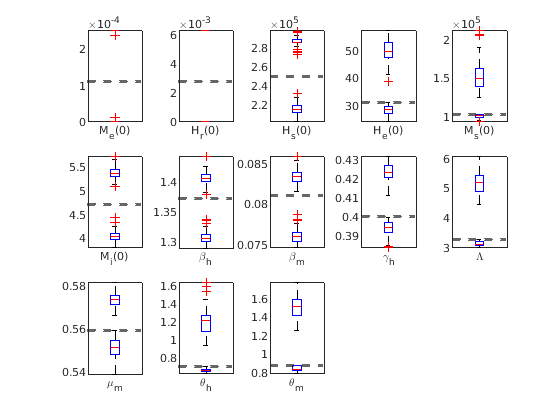

load("Results/CSB/CSBRangeProtected_skewness_N_5000")

Np = 13;
D1 = floor(sqrt(Np));%Number of subplots
D2 = D1+ceil((Np-D1^2)/D1);%Number of subplots

clf
for i=1:Np
    subplot(D1,D2,i)
    boxplot(Low(i,:))
    hold on
    boxplot(Up(i, :),'Labels',T_oat.Properties.RowNames{i})
    set(gca, 'TickLabelInterpreter', 'tex');
    ylim([min(Low(i,:)) max(Up(i,:))])
    yline(Deep(i),'--', 'linewidth',2)
end

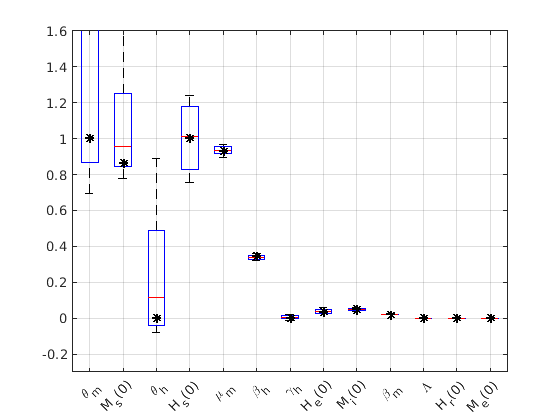

range = T.Range;
NInter = ([Low,Up] - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (Deep - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Deep(idx);

boxplot(NInter')
hold on
plot(1:13,Deep,'*', 'color', 'k', 'linewidth',2)
ylim([-0.3 1.6])
set(gca,'xticklabel',Names)
set(gca, 'TickLabelInterpreter', 'tex');
grid on

Estimate the uniqueness index

unity(Up,Low,T_oat.Range)

ans = 0.8773

**Plot the histograms for upper and lower CSB intervals estimated**

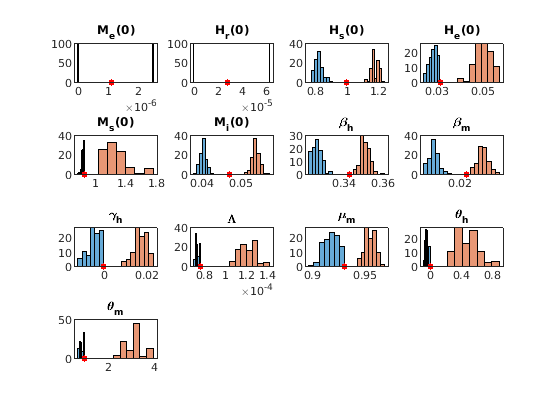

range = T.Range;
LowN = (Low - range(:,1))./(range(:,2)-range(:,1));
UpN = (Up - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (Deep - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Deep = Best(idx);

LowN = LowN(idx,:);
UpN = UpN(idx,:);

for i = 1:13
    subplot(4,4,i)
    histogram(LowN(i,:),'BinLimits',[min(LowN(i,:)), max(LowN(i,:))])
    hold on
    histogram(UpN(i,:),'BinLimits',[min(UpN(i,:)), max(UpN(i,:))])
    plot(Best(i), 0, 'r.','MarkerSize',16)
    title(Names(i))
end

**1.2. SA: median of multiple CSB estimations**

MedianUp = median(Up');
MedianLow = median(Low');
T.Range(:,1) = MedianLow;
T.Range(:,2) = MedianUp;
N = 10000; 
M = gsua_dmatrix(T, N, 'Method', 'Sobol');
T_sa = gsua_sa(M, T);

Progress: 7%
Estimated processing time (h:m:s): 0:2:52
Remaining time (h:m:s): 0:2:40
Elapsed time (h:m:s): 0:0:11
Estimated stop time (h:m:s): 15:49:2
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:2:34
Remaining time (h:m:s): 0:2:13
Elapsed time (h:m:s): 0:0:20
Estimated stop time (h:m:s): 15:48:44
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:2:26
Remaining time (h:m:s): 0:1:57
Elapsed time (h:m:s): 0:0:29
Estimated stop time (h:m:s): 15:48:36
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:2:22
Remaining time (h:m:s): 0:1:44
Elapsed time (h:m:s): 0:0:38
Estimated stop time (h:m:s): 15:48:32
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:2:20
Remaining time (h:m:s): 0:1:33
Elapsed time (h:m:s): 0:0:46
Estimated stop time (h:m:s): 15:48:30
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:2:19
Remaining time (h:m:s): 0:1:23


sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 1.0000

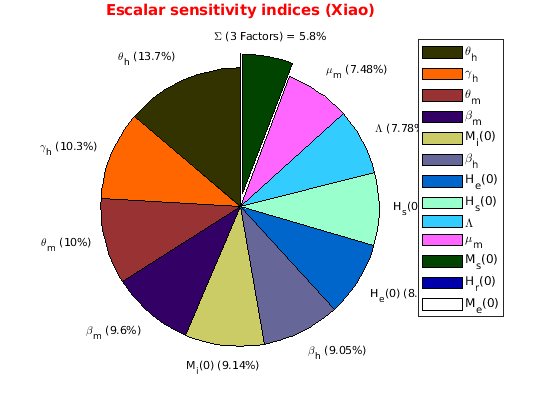

clf
gsua_plot('Pie',T_sa,T_sa.STi)

**1.3. SA: random CSB estimation**

T.Range(:,1) = Low(:,50);
T.Range(:,2) = Up(:,50);
N = 10000; 
M = gsua_dmatrix(T, N, 'Method', 'Sobol');
T_sa = gsua_sa(M, T);

Progress: 7%
Estimated processing time (h:m:s): 0:1:20
Remaining time (h:m:s): 0:1:15
Elapsed time (h:m:s): 0:0:5
Estimated stop time (h:m:s): 14:50:13
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:1:20
Remaining time (h:m:s): 0:1:9
Elapsed time (h:m:s): 0:0:10
Estimated stop time (h:m:s): 14:50:12
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:1:19
Remaining time (h:m:s): 0:1:3
Elapsed time (h:m:s): 0:0:15
Estimated stop time (h:m:s): 14:50:11
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:1:19
Remaining time (h:m:s): 0:0:58
Elapsed time (h:m:s): 0:0:21
Estimated stop time (h:m:s): 14:50:11
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:1:19
Remaining time (h:m:s): 0:0:52
Elapsed time (h:m:s): 0:0:26
Estimated stop time (h:m:s): 14:50:11
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:1:18
Remaining time (h:m:s): 0:0:47
El

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 1

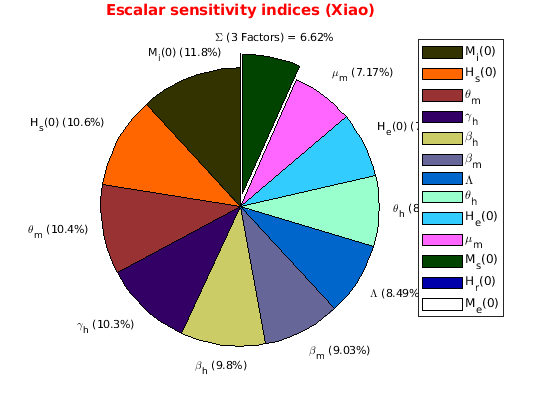

clf
gsua_plot('Pie',T_sa,T_sa.STi)

**2. CSB estimation: withou protecting the nominal value **

N = 5000;
Experiments = 100;
reps = 200;
Up = zeros(13, Experiments);
Low = zeros(13, Experiments);
In = zeros(1, Experiments);

parfor i = 1 : Experiments
    [ParU, ~, ~, ~,sup] = gsua_csb(T_oat, N, 'reps', reps, 'protect', false)
    Low(:, i) = ParU.Range(:, 1);
    Up(:, i) = ParU.Range(:, 2);
    In(i) = max(sup);
    Iters(i) = find(sup == max(sup))
end

save("Results/CSB/CSBRangeUnProtected_skewness_N_5000", "Low","Up", "In")

**2.1. CSB estimation: Uniqueness without protecting the nominal value**

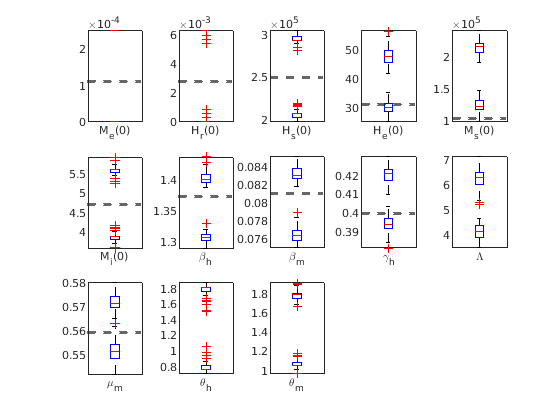

load("Results/CSB/CSBRangeUnProtected_skewness_N_5000.mat" )

Np = 13;
D1 = floor(sqrt(Np));%Number of subplots
D2 = D1+ceil((Np-D1^2)/D1);%Number of subplots

for i=1:Np
    subplot(D1,D2,i)
    boxplot(Low(i,:))
    hold on
    boxplot(Up(i, :),'Labels',T_oat.Properties.RowNames{i})
    set(gca, 'TickLabelInterpreter', 'tex');
    ylim([min(Low(i,:)) max(Up(i,:))])
    yline(BestParams(i),'--', 'linewidth',2)
end

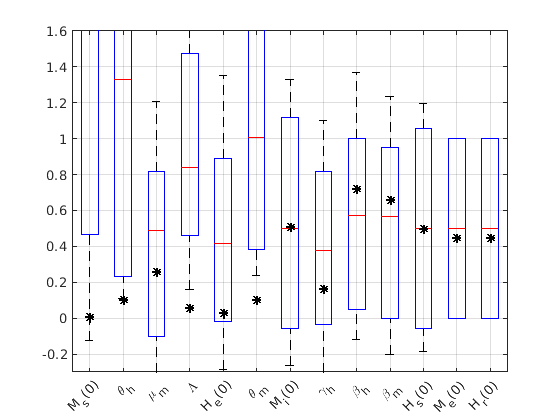

range = T.Range;
NInter = ([Low,Up] - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (BestParams' - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

boxplot(NInter')
hold on
plot(1:13,Best,'*', 'color', 'k', 'linewidth',2)
ylim([-0.3 1.6])
set(gca,'xticklabel',Names)
set(gca, 'TickLabelInterpreter', 'tex');
grid on

Estimate the uniqueness index

res = unity(Up,Low,T_oat.Range)

res = 0.8765

**Plot the histograms for upper and lower CSB intervals estimated**

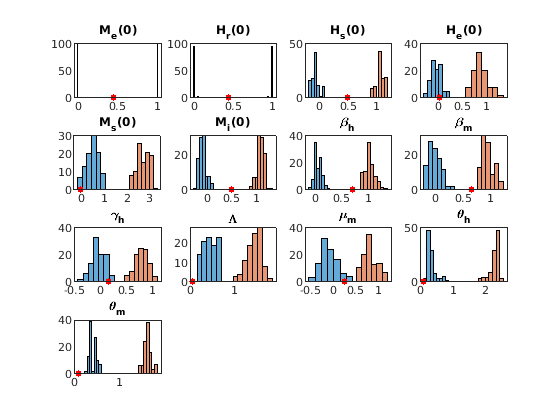

range = T.Range;
LowN = (Low - range(:,1))./(range(:,2)-range(:,1));
UpN = (Up - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (BestParams' - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

LowN = LowN(idx,:);
UpN = UpN(idx,:);

for i = 1:13
    subplot(4,4,i)
    histogram(LowN(i,:),'BinLimits',[min(LowN(i,:)), max(LowN(i,:))])
    hold on
    histogram(UpN(i,:),'BinLimits',[min(UpN(i,:)), max(UpN(i,:))])
    plot(Best(i), 0, 'r.','MarkerSize',16)
    title(Names(i))
end

**2.2. SA: median of multiple CSB estimations**

MedianUp = median(Up');
MedianLow = median(Low');
T.Range(:,1) = MedianLow;
T.Range(:,2) = MedianUp;

N = 10000; 
M = gsua_dmatrix(T, N, 'Method', 'Sobol');
T_sa = gsua_sa(M, T);

Progress: 7%
Estimated processing time (h:m:s): 0:1:27
Remaining time (h:m:s): 0:1:22
Elapsed time (h:m:s): 0:0:5
Estimated stop time (h:m:s): 14:52:58
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:1:25
Remaining time (h:m:s): 0:1:14
Elapsed time (h:m:s): 0:0:11
Estimated stop time (h:m:s): 14:52:56
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:1:28
Remaining time (h:m:s): 0:1:11
Elapsed time (h:m:s): 0:0:17
Estimated stop time (h:m:s): 14:52:59
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:1:32
Remaining time (h:m:s): 0:1:7
Elapsed time (h:m:s): 0:0:24
Estimated stop time (h:m:s): 14:53:2
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:1:33
Remaining time (h:m:s): 0:1:2
Elapsed time (h:m:s): 0:0:31
Estimated stop time (h:m:s): 14:53:3
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:1:33
Remaining time (h:m:s): 0:0:56
Elap

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 1.0000

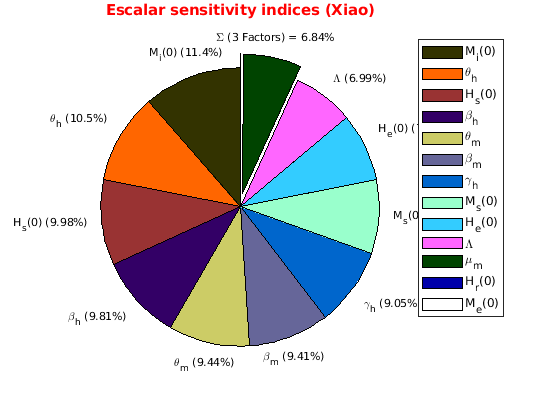

clf
gsua_plot('Pie',T_sa,T_sa.STi)

**2.3. SA: random CSB estimation**

T.Range(:,1) = Low(:,50);
T.Range(:,2) = Up(:,50);
N = 10000; 
M = gsua_dmatrix(T, N, 'Method', 'Sobol');
T_sa = gsua_sa(M, T);

Progress: 7%
Estimated processing time (h:m:s): 0:1:11
Remaining time (h:m:s): 0:1:6
Elapsed time (h:m:s): 0:0:4
Estimated stop time (h:m:s): 14:55:5
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:1:10
Remaining time (h:m:s): 0:1:1
Elapsed time (h:m:s): 0:0:9
Estimated stop time (h:m:s): 14:55:5
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:1:11
Remaining time (h:m:s): 0:0:56
Elapsed time (h:m:s): 0:0:14
Estimated stop time (h:m:s): 14:55:5
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:1:10
Remaining time (h:m:s): 0:0:51
Elapsed time (h:m:s): 0:0:18
Estimated stop time (h:m:s): 14:55:4
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:1:10
Remaining time (h:m:s): 0:0:47
Elapsed time (h:m:s): 0:0:23
Estimated stop time (h:m:s): 14:55:4
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:1:10
Remaining time (h:m:s): 0:0:42
Elapsed 

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 1.0000

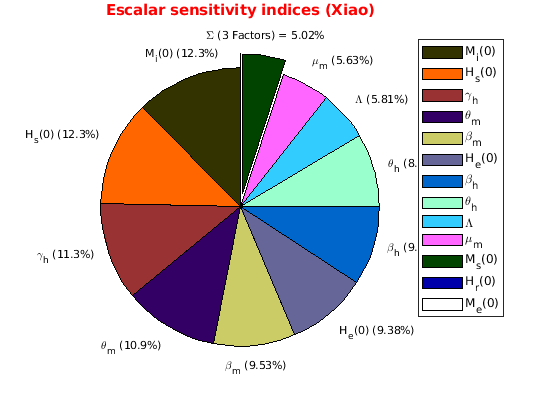

clf
gsua_plot('Pie',T_sa,T_sa.STi)

# **Performance with multiple number of samples (140, 500, 1000, 2000)**

N = [140, 500, 1000, 2000];
Experiments = 100;
reps = 200;

for j = 1 : length(N)
    Up = zeros(13, Experiments);
    Low = zeros(13, Experiments);
    In = zeros(1, Experiments);
    err = zeros(1, Experiments);
    Iters = zeros(1, Experiments);
    parfor i = 1 : Experiments
        [ParU, ~, ~, ~,sup, E] = gsua_csb(T_oat, N(j), 'reps', reps, 'protect', true);
        Low(:, i) = ParU.Range(:, 1);
        Up(:, i) = ParU.Range(:, 2);
        In(i) = max(sup);
        Iters(i) = find(sup == max(sup), 1, 'last' );
        err(i) = max(abs(E));
    end
    save("Results/CSB/CSBRangeProtected_skewness_N_" + num2str(N(j)), "Low","Up", "In", "Iters","err")
end